# Equazioni differenziali ordinarie

Con questo elaborato si vuole analizzare la suite ode offerta dal `Matlab` per risolvere equazioni o sistemi di equazioni differenziali ordinarie.

## *Modello SIR di diffusione di un’epidemia.*

Calcolare con la function matlab `ode45` la soluzione del seguente sistema:


$$S^{\prime } \left(t\right)=-\alpha S\left(t\right)I\left(t\right)$$



$$I^{\prime } \left(t\right)=\alpha S\left(t\right)I\left(t\right)-\mathrm{bI}\left(t\right)$$



$$R^{\prime } \left(t\right)=\mathrm{bI}\left(t\right)$$


Con: $t\in \left\lbrack 0,20\right\rbrack ,\;\;S\left(0\right)=199,\;I\left(0\right)=1,\;R\left(0\right)=0$

Dove:

$S$ = Suscettibili di infezione, $I$ =Infetti, $R$ = Immuni(guariti), $a$ = costante di contagio, $b$ = costante di guarigione.

Per poter calcolare e effettuare le simulazioni al variare di $a$, andamento della diffusione dell'epidemia, è stato relizzata una function che calcola la soluzione del sistema di equazioni della diffusione dell'epidemia. Il codice sorgente è presente in s`imulazioneEpidemia.m`.

Prima di procedere con la simulazione, definiamo le costanti del problema e le soluzioni iniziali per analizzare un esempio di  applicazione di `ode45 `al fine di calcolare la soluzione del sistema.

% Costante definite dalla traccia
b = 0.1;
tInterval = [0, 20];
a = [0.005 0.01 0.05 0.1];

% Soluzioni iniziali
% numero di scettibili iniziali
% numero di infetti iniziali
% numero di guariti iniziali
y0 = [199; 1 ;0];

Dalle soluzioni iniziali del problema di Cauchy osserviamo che il numero totale di individui è `200,` di cui 1`99` individui sono suscettibili all'infezione, uno solo è infetto e non c'è nessun immune. 

Analizziamo ora come usare `ode45 `e quali sono i risultati che ci fornisce. 

[t,y] = ode45(@sistemaEpidemia, tInterval, y0, [], a(1), b);
% per compattezza mostriamo solo i primi 15 risultati invece dei 73 ottenuti
T = table(t(1:15),y(1:15,1),y(1:15,2),y(1:15,3));
T.Properties.VariableNames = {'Tempo' 'Suscettibili' 'Infetti' 'Immuni'}

T = 15×4 table
      Tempo       Suscettibili    Infetti      Immuni  
    __________    ____________    _______    __________

             0          199            1              0
    0.00050238          199       1.0004     5.0249e-05
     0.0010048          199       1.0009     0.00010052
     0.0015071          199       1.0013     0.00015081
     0.0020095          199       1.0018     0.00020113
     0.0045214          199       1.0041     0.00045306
     0.0070333       198.99       1.0063     0.00070555
     0.0095452       198.99       1.0086     0.00095861
      0.012057       198.99       1.0108      0.0012122
      0.024616       198.98       1.0223       0.002489
      0.037176       198.96       1.0338      0.0037801
      0.049735       198.95       1.0455      0.0050859
      0.062295       198.94       1.0573      0.0064064
       0

la funzione ci fornisce gli istanti di tempo che utilizza per calcolare la soluzione e osserviamo subito che il passo che utilizza per la discretizzazione è variabile e che il numero di punti e il passo non sono scelti da noi. Oltre agli instanti di tempo `ode` ci fornisce anche `y`, matrice che contiene i valori delle funzioni negli istanti di tempo considerati.

## Analisi dei risultati al variare della costante di contagio 

In questa sezione andremo ad analizzare cosa accade al variare della costante di contagio.

**Nota:** Si riportano le immagini catturate, in quanto i grafici relizzati con il live script potrebbero risultare piccoli e non si riuscirebbe ad apprezzare i risultati ottenuti

**Test con costante di contagio pari a 0.005**

simulazioneEpidemia(y0,tInterval,a(1),b)

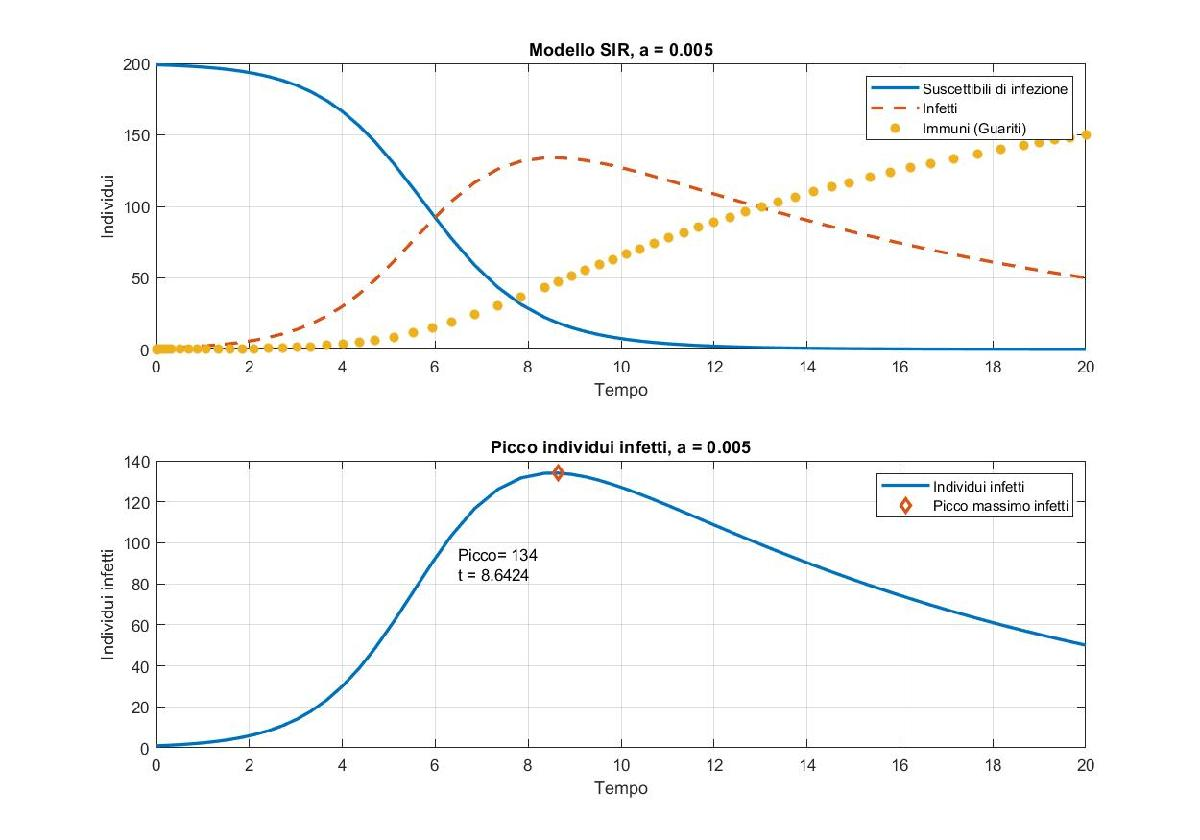

**Test con costante di contagio pari a 0.01**

simulazioneEpidemia(y0,tInterval,a(2),b)

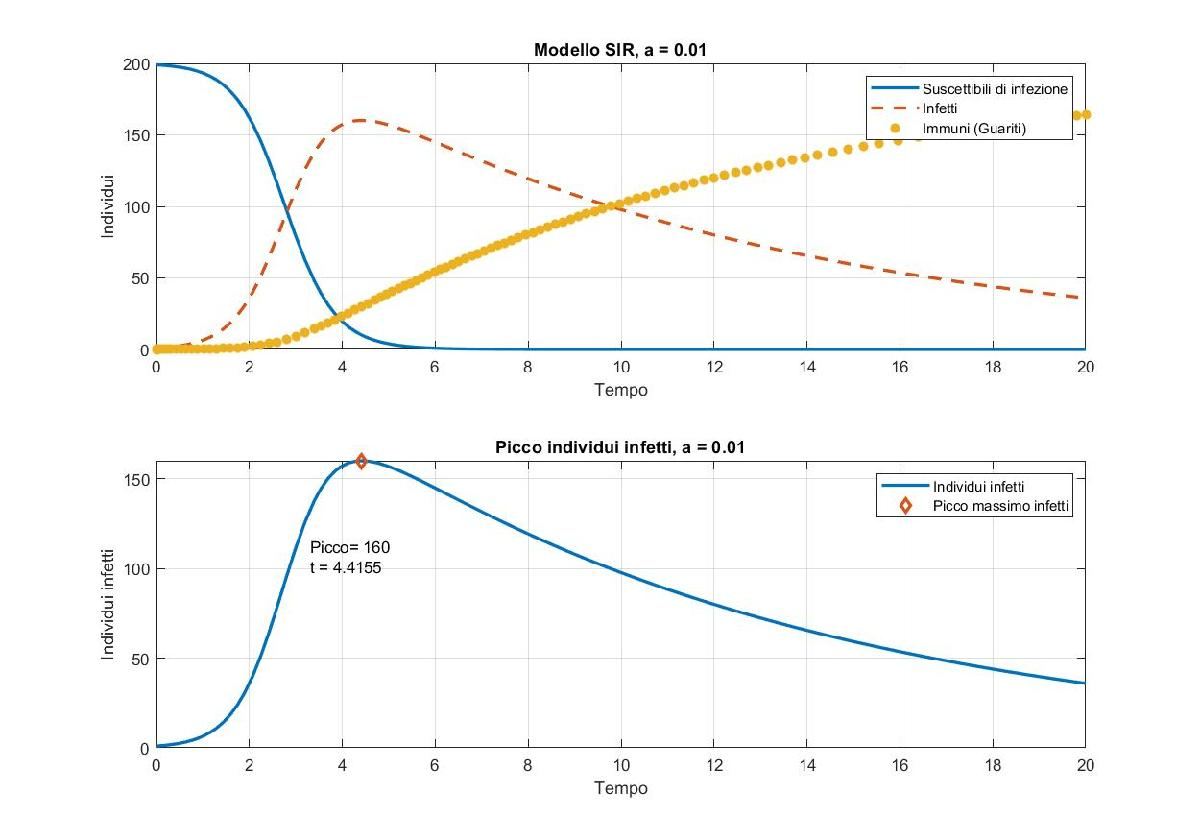

**Test con costante di contagio pari a 0.05**

simulazioneEpidemia(y0,tInterval,a(3),b)

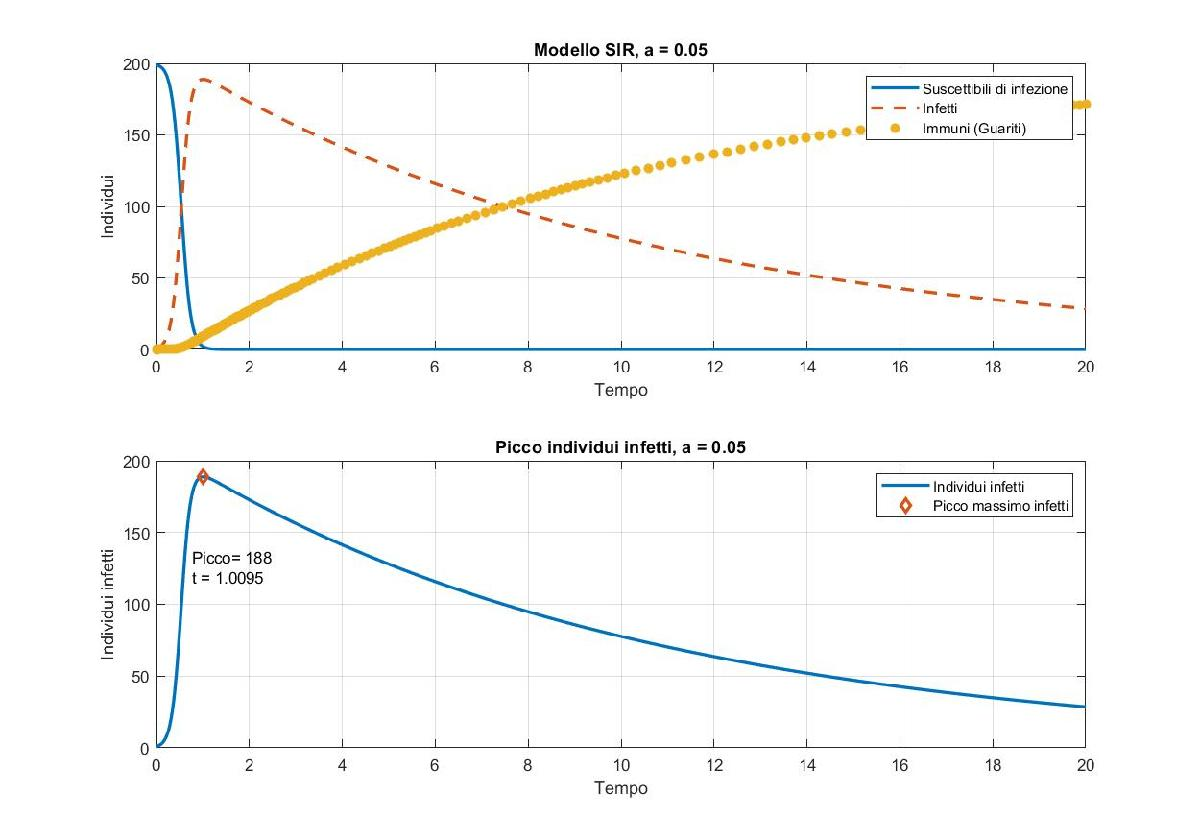

**Test con costante di contagio pari a 0.1**

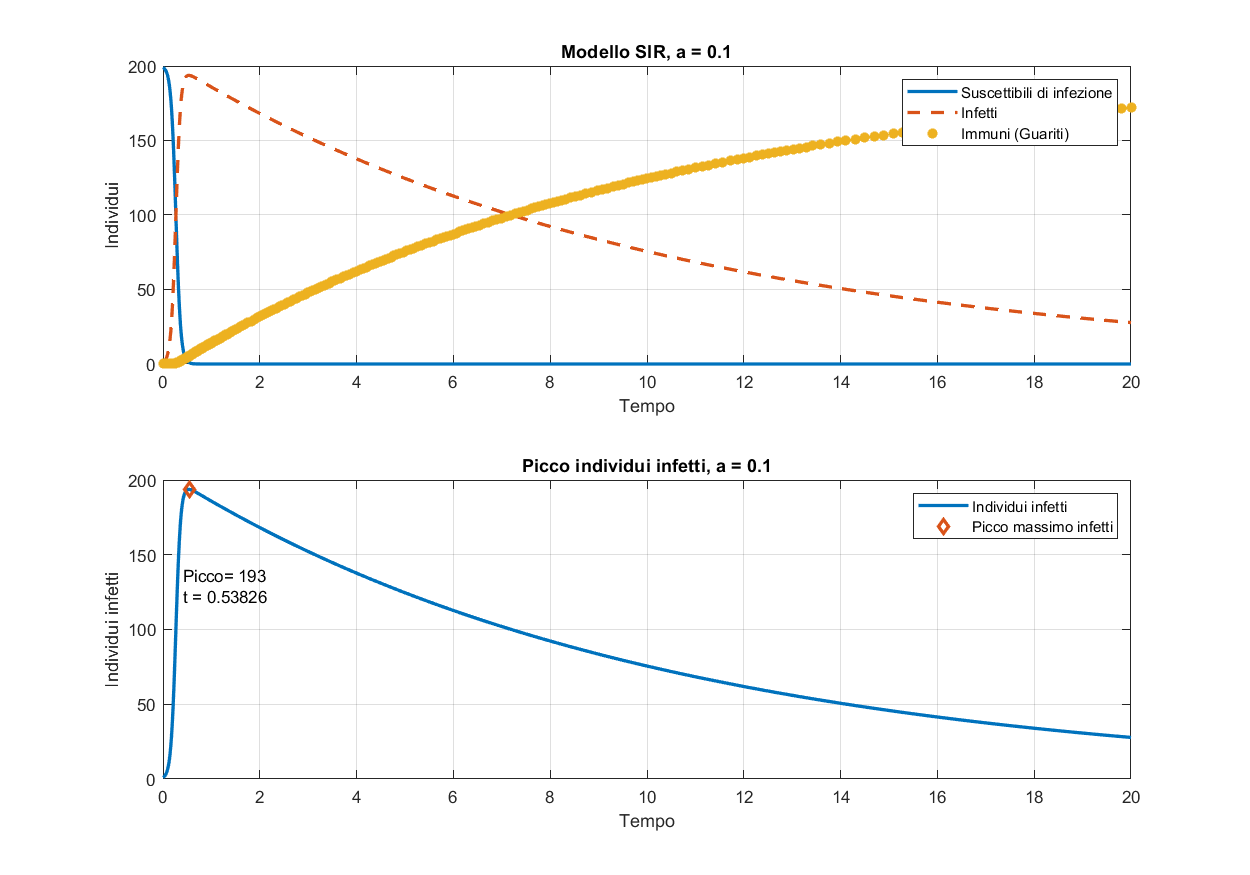

simulazioneEpidemia(y0,tInterval,a(4),b)

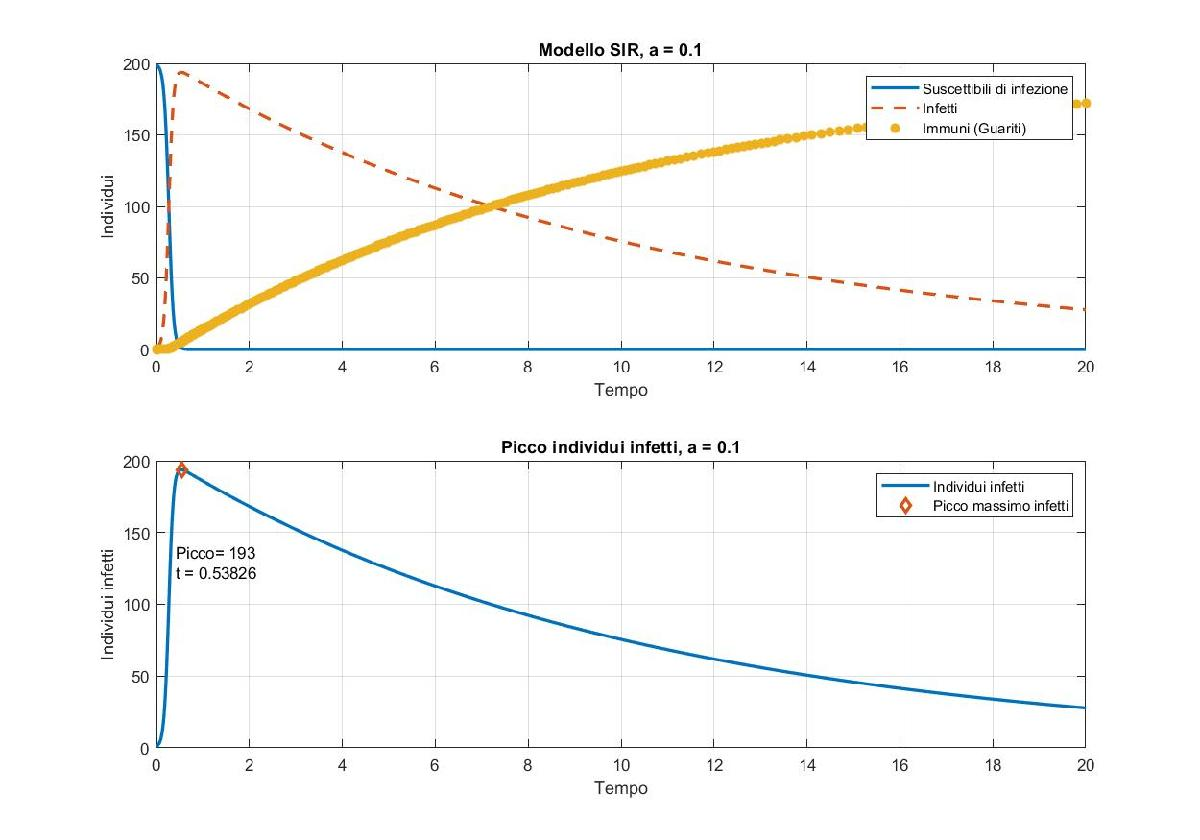

**Osservazioni e conclusioni sui risultati**

Dalle simulazioni precedenti si osserva che al variare della costante di contagio varia la velocità di contagio, quindi a parità di tempo trascorso il numero di infetti saranno maggiori e di conseguenza anche il picco degli infetti aumenta al aumentare della costante di contagio spostandosi verso sinistra. Si osserva inoltre che al variare di $a$ varia anche l'andamento dei suscettibili e dei guariti. Infatti i suscettibili diminuiscono all'aumentare degli infetti e mentre l'infezione sta procedendo nel contagio dei suscettibili, quelli infetti iniziano a guarire con una costante di guarigione fissata. Tale costante anche se fissata produce un andament diverso al variare di $a$ perchè proprio il numero di infetti varia e di conseguenza varierà anche l'andamento degl infetti.

Di seguito riportiamo analiticamente il numero degli infetti e gli istanti di tempo in cui si verifica il picco degli infetti al variare di $a$.

timePiccoInfetti = zeros(1,4); valuePiccoInfetti = zeros(1,4); indexPiccoInfetti = 0;
for i=1:4
    [time,value] = ode45(@sistemaEpidemia, tInterval, y0, [], a(i), b);  
    indexPiccoInfetti = find(value(:, 2) == max(value(:,2)));   
    timePiccoInfetti(i) = time(indexPiccoInfetti);
    valuePiccoInfetti(i) = value(indexPiccoInfetti,2);
end
T = table(a',timePiccoInfetti',ceil(valuePiccoInfetti)');
T.Properties.VariableNames = {'a' 't_Picco' 'Picco'}

T = 4×3 table
      a      t_Picco    Picco
    _____    _______    _____

    0.005     8.6424     135 
     0.01     4.4155     161 
     0.05     1.0095     189 
      0.1    0.53826     194 


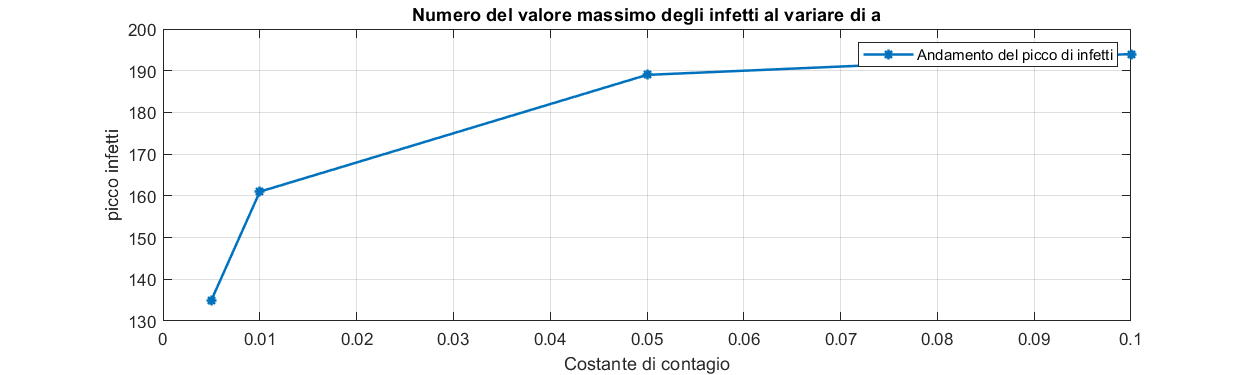

plot(a,ceil(valuePiccoInfetti),'-*','LineWidth',1.5), grid
title('Numero del valore massimo degli infetti al variare di a')
legend('Andamento del picco di infetti')
xlabel('Costante di contagio')
ylabel('picco infetti')

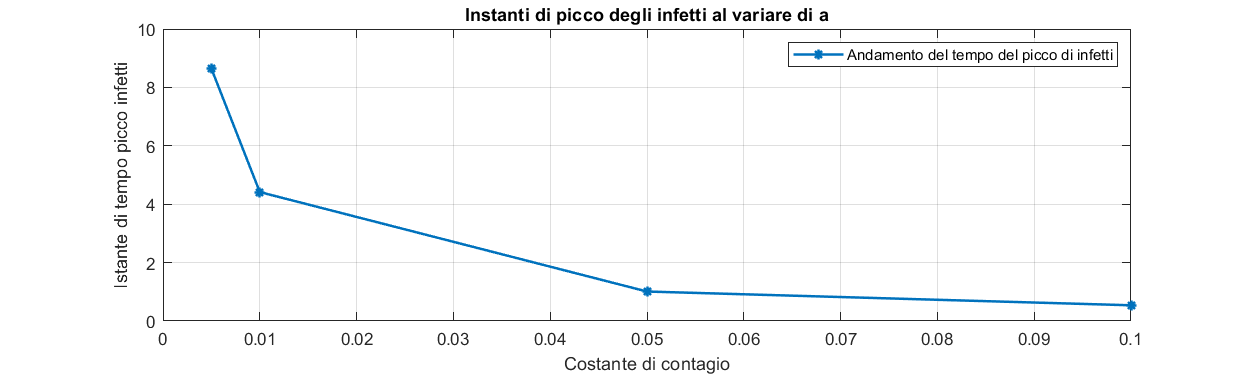

plot(a,timePiccoInfetti,'-*','LineWidth',1.5), grid
title('Instanti di picco degli infetti al variare di a')
legend('Andamento del tempo del picco di infetti')
xlabel('Costante di contagio')
ylabel('Istante di tempo picco infetti')

## Simulazione live dell'andamento

Si lascia in questa sezione la possibilità di variare il costante di contaggio e vedere come varia l'andamento dell'epidemia

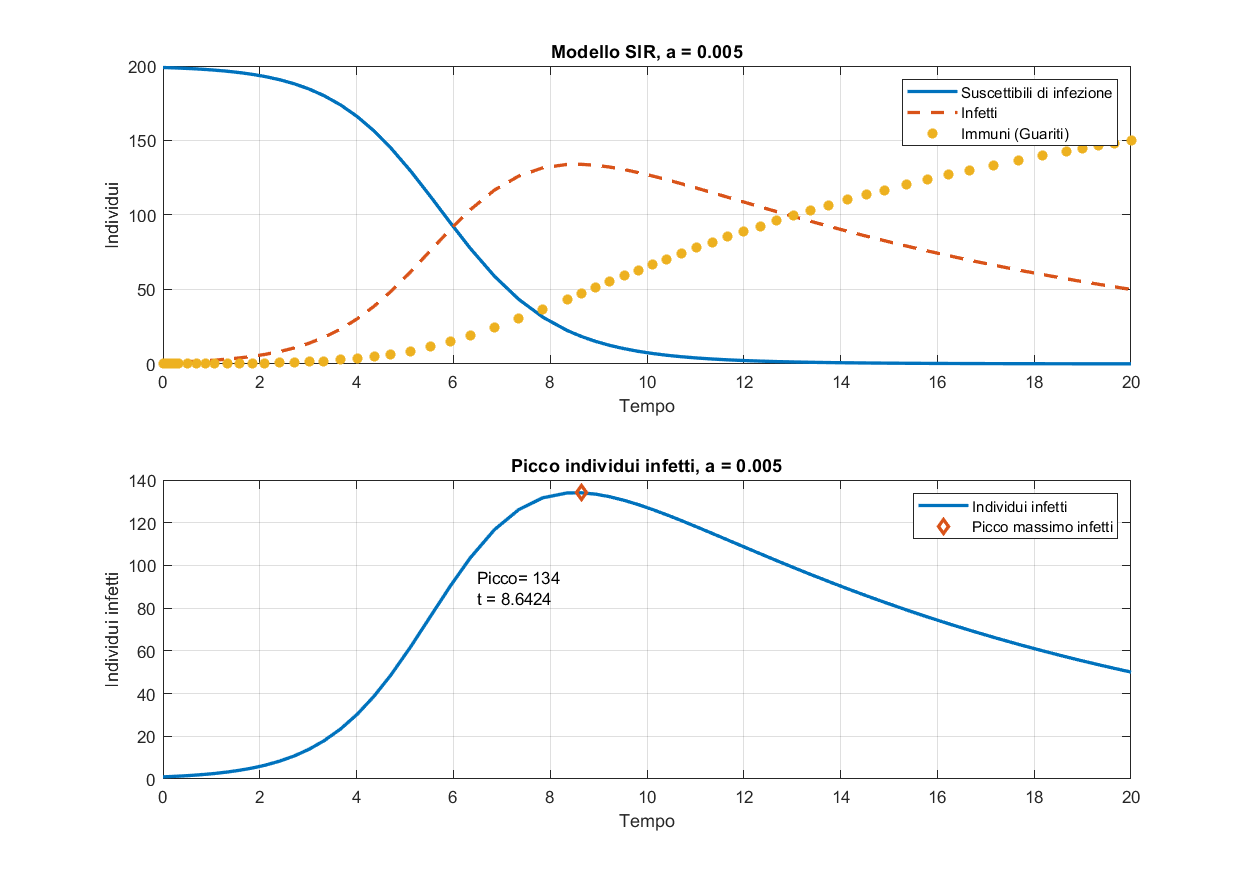

simulazioneEpidemia(y0,t,0.005,b)

# Problema chimico ( Oregonator )

E’ un modello di reazioni chimiche tra tre sostanze che, dopo un periodo di inattività, presentano oscillazioni in cui cambia struttura e colore. Tale modello chimico è espresso dal sistema di equazioni differenziali: 


$${y^{\prime } }_1 =\frac{qy_2 -y_1 y_2 +y_1 \left(1-y_1 \right)}{e}$$



$${y^{\prime } }_2 =\frac{-qy_2 -y_1 y_2 +fy_3 }{g}$$



$${y^{\prime } }_3 =y_1 -y_3$$


da valutare in $t\in \left\lbrack 0,50\right\rbrack$, con


$$y_1 \left(0\right)=0\ldotp 2,y_2 \left(0\right)=0\ldotp 2,{\;y}_3 \left(0\right)=0\ldotp 2$$



$$q=9\mathrm{x}{10}^{-5} ,e={10}^{-2} ,g=2\ldotp 5\mathrm{x}{10}^{-5} ,f=0\ldotp 8$$


Utilizzare le function `ode45` e `ode15s` per la risoluzione, con `RelTol`=10^-6, `AbsTol`=10^-7. Fare il grafico delle soluzioni con `plot` e `semilog.`

t  = [0, 50];
y0 = [0.2 0.2 0.2];
% setto i valori di errore relativo e assoluto come dettati dal problema
opts = odeset('RelTol',1e-6,'AbsTol',1e-7);


Iniziamo con l'utilizzo di `ode45 `per risolvere il sistema di equazioni differenziali` :`

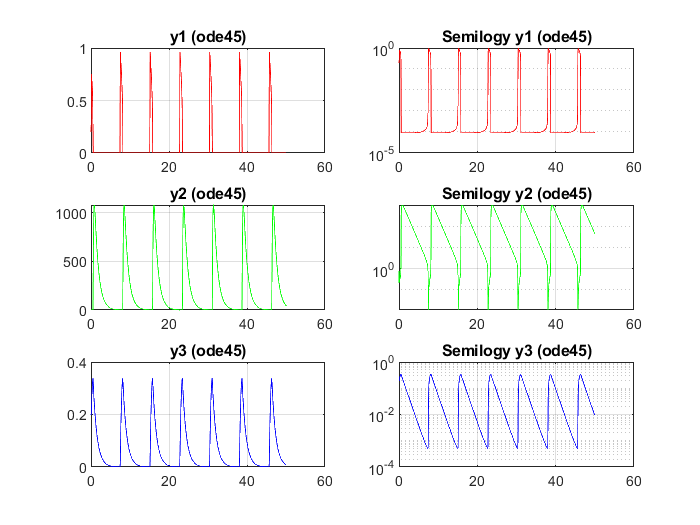

[tOde45, yOde45] = ode45(@oregonator, t, y0,opts);

figure
subplot(3,2,1);plot(tOde45,yOde45(:,1),'r'), grid;
title('y1 (ode45)');
subplot(3,2,3);plot(tOde45,yOde45(:,2),'g'), grid;
title('y2 (ode45)');
subplot(3,2,5);plot(tOde45,yOde45(:,3),'b'), grid;
title('y3 (ode45)');
  
subplot(3,2,2);semilogy(tOde45,yOde45(:,1),'r'), grid;
title('Semilogy y1 (ode45)');
subplot(3,2,4);semilogy(tOde45,yOde45(:,2),'g'), grid;
title('Semilogy y2 (ode45)');
subplot(3,2,6);semilogy(tOde45,yOde45(:,3),'b'), grid;
title('Semilogy y3 (ode45)');

Utiizziamo ora `ode15s `per risolvere il medesimo sistema `:`

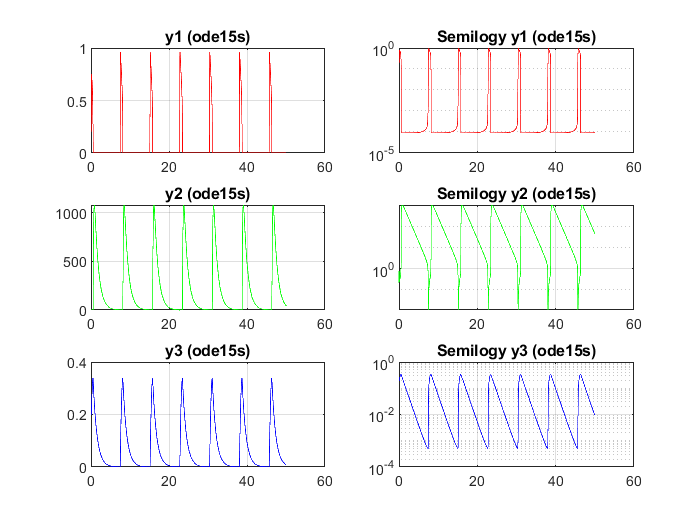

[tOde15s, yOde15s] = ode15s(@oregonator, t, y0,opts);

figure
subplot(321);plot(tOde15s,yOde15s(:,1),'r'), grid;
title('y1 (ode15s)');
subplot(323);plot(tOde15s,yOde15s(:,2),'g'), grid;
title('y2 (ode15s)');
subplot(325);plot(tOde15s,yOde15s(:,3),'b'), grid;
title('y3 (ode15s)');
    
subplot(322);semilogy(tOde15s,yOde15s(:,1),'r'), grid;
title('Semilogy y1 (ode15s)');
subplot(324);semilogy(tOde15s,yOde15s(:,2),'g'), grid;
title('Semilogy y2 (ode15s)');
subplot(326);semilogy(tOde15s,yOde15s(:,3),'b'), grid;   
title('Semilogy y3 (ode15s)');

I risultati ottenuti sembrano identici, ma andiamo a confrontare analiticamente i tre andamenti ottenuti applicando `ode45` e `ode15s `.

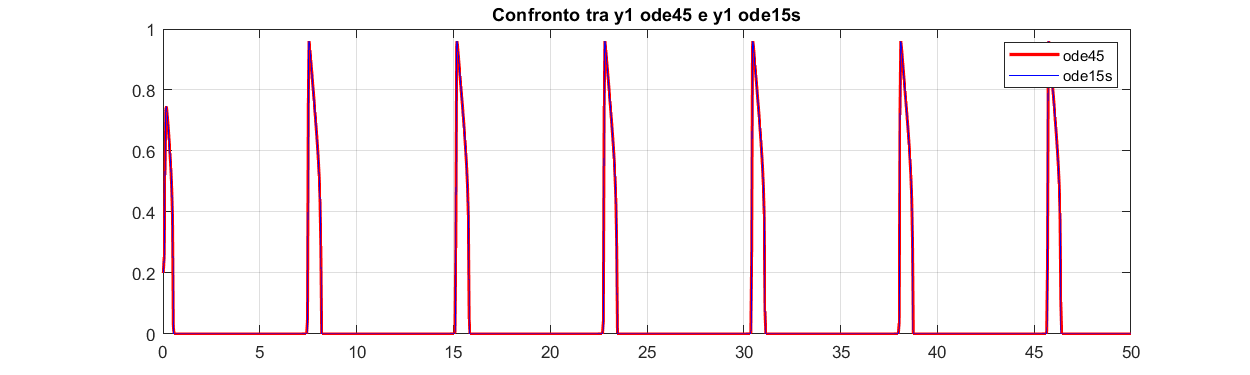

figure
p = plot(tOde45,yOde45(:,1),'r',tOde15s,yOde15s(:,1),'b');
p(1).LineWidth=2; set(gcf,'position',[0,0,1000,300]);
legend('ode45','ode15s'), grid
title('Confronto tra y1 ode45 e y1 ode15s');

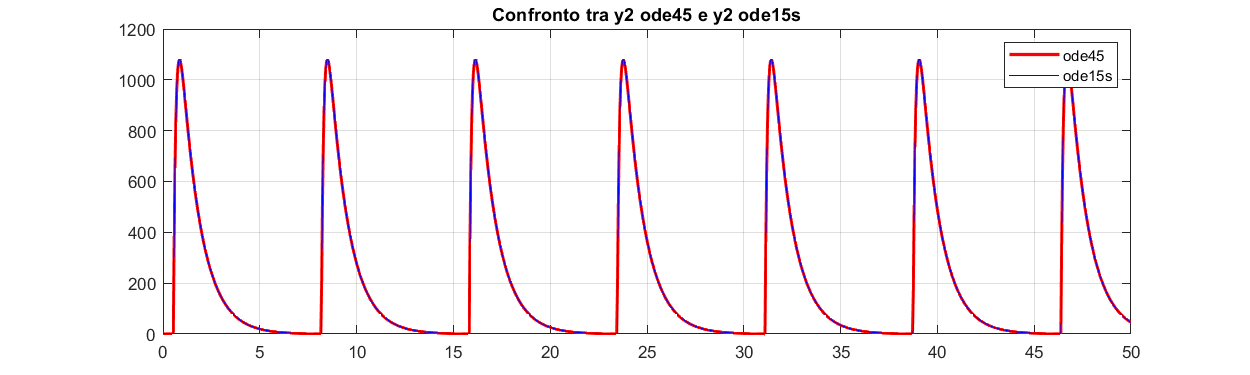

p = plot(tOde45,yOde45(:,2),'r',tOde15s,yOde15s(:,2),'b');
p(1).LineWidth=2; set(gcf,'position',[0,0,1000,300]);
legend('ode45','ode15s'), grid
title('Confronto tra y2 ode45 e y2 ode15s');

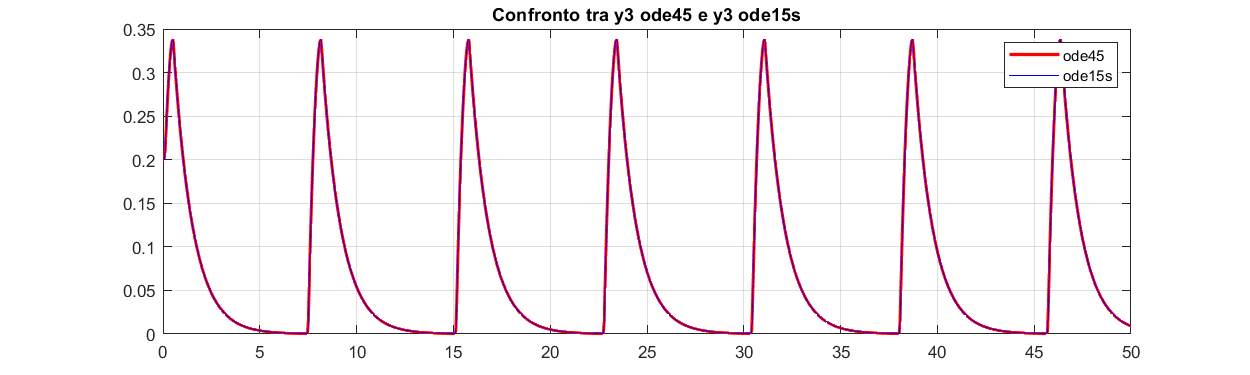

p = plot(tOde45,yOde45(:,3),'r',tOde15s,yOde15s(:,3),'b');
set(gcf,'position',[0,0,1000,300]);
p(1).LineWidth=2;
legend('ode45','ode15s'), grid
title('Confronto tra y3 ode45 e y3 ode15s');

Dai grafici generati, possiamo verificare che l'affermazione fatta all'inizio della sezione è corretta, cioè che fissati i parametri di tolleranza gli andamenti sono identici.

Possiamo, però, fare un ulteriore confronto tra i risultati ottenuti con `ode45` e con `ode15s`.In particolare andremo a confrontare il numero di punti necessari all'algorimo per convergere e il tempo impiegato per ottenure il risultato con l'accuratezza voluta .

fOde45 = @()ode45(@oregonator, t, y0,opts);
timeOde45 = timeit(fOde45)

timeOde45 = 6.1858

lengthOde45 = length(tOde45)

lengthOde45 = 1402461

fOde15s = @()ode15s(@oregonator, t, y0,opts);
timeOde15s = timeit(fOde15s)

timeOde15s = 0.6879

lengthOde15s = length(tOde15s)

lengthOde15s = 3695

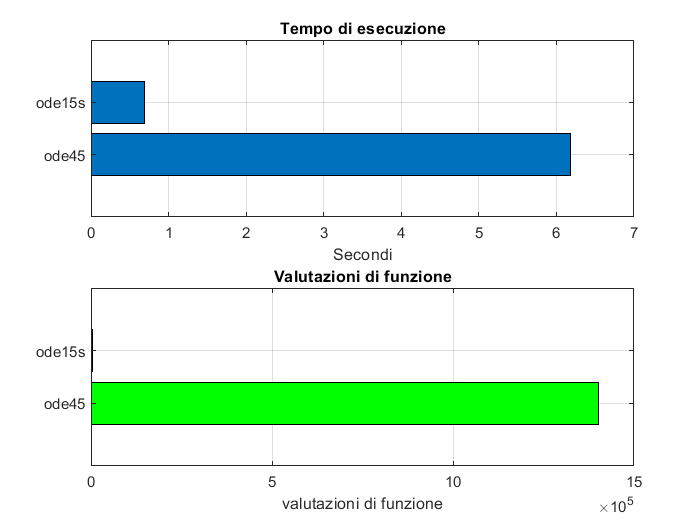

figure
subplot(2,1,1)
barh([timeOde45 timeOde15s])
set(gca,'yticklabel',{'ode45'; 'ode15s'}), grid
title('Tempo di esecuzione'),xlabel('Secondi')
subplot(2,1,2)
barh([lengthOde45 lengthOde15s],'green')
set(gca,'yticklabel',{'ode45'; 'ode15s'}), grid
title('Valutazioni di funzione'),xlabel('valutazioni di funzione')

Dai grafici e dai singoli valori, possiamo osservare che il sistema è `stiff`, in quanto il tempo necessario e il numero di punti per ottenere la soluzione del sistema è nettamente inferiore nel caso in cui utilizziamo `ode15s `rispetto al caso in cui utilizziamo `ode45`. Pertanto mettendo insieme tutti i risultati ottenuti, possiamo affermare che se un problema è `difficile`, non significa che `ode45 `non trovi la soluzione ( fissata la tolleranza voluta ) ma che impiega un tempo di esecuzione maggiore rispetto a `ode15s `e pertanto è meglio utilizzare `ode15s` per ottenere la soluzione di questo tipo di problemi .